% AAE666 HW2 EXERCISE3 MATLAB SCRIPT    
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2021-Spring\AAE666\matlab\hw2';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

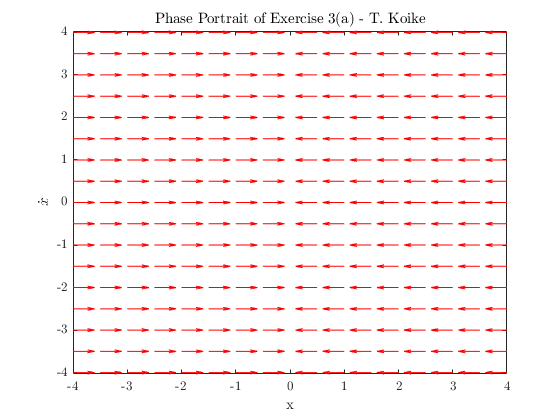

% (a)
f = @(t,x) [-x(1)-x(1)^3;0];
fig = vectfield(f,-4:0.5:4,-4:0.5:4);
hold on
for y20=-4:0.2:4
  [ts,ys] = ode45(f,[0,10],[0;y20]);
  plot(ys(:,1),ys(:,2))
end
hold off
title('Phase Portrait of Exercise 3(a) - T. Koike')
xlabel('x')
ylabel('$\dot{x}$')
saveas(fig, fullfile(fdir, "ex3a-phase-portrait.png"));

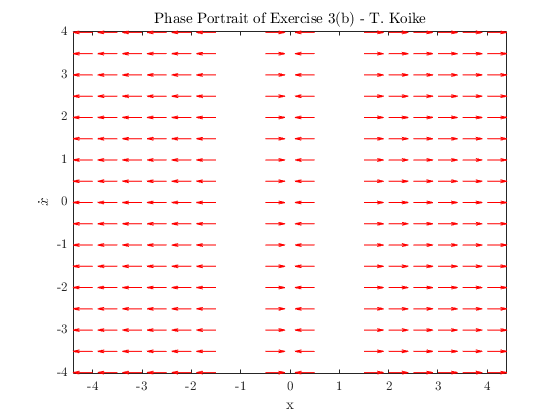

% (b)
f = @(t,x) [-x(1)+x(1)^3;0];
fig = vectfield(f,-4:0.5:4,-4:0.5:4);
hold on
for y20=-4:0.2:4
  [ts,ys] = ode45(f,[0,10],[0;y20]);
  plot(ys(:,1),ys(:,2))
end
hold off
title('Phase Portrait of Exercise 3(b) - T. Koike')
xlabel('x')
ylabel('$\dot{x}$')
saveas(fig, fullfile(fdir, "ex3b-phase-portrait.png"));

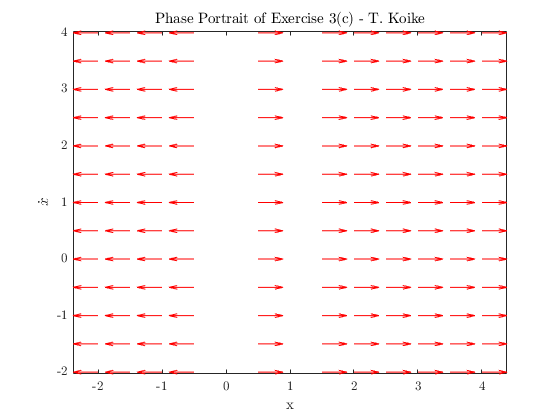

% (c)
f = @(t,x) [x(1)-2*x(1)^2+x(1)^3;0];
fig = vectfield(f,-2:0.5:4,-2:0.5:4);
hold on
for y20=-2:0.2:4
  [ts,ys] = ode45(f,[0,10],[0;y20]);
  plot(ys(:,1),ys(:,2))
end
hold off
title('Phase Portrait of Exercise 3(c) - T. Koike')
xlabel('x')
ylabel('$\dot{x}$')
saveas(fig, fullfile(fdir, "ex3c-phase-portrait.png"));

function fig = vectfield(func,y1val,y2val,t)
    if nargin==3
      t=0;
    end
    n1=length(y1val);
    n2=length(y2val);
    yp1=zeros(n2,n1);
    yp2=zeros(n2,n1);
    for i=1:n1
      for j=1:n2
        ypv = feval(func,t,[y1val(i);y2val(j)]);
        yp1(j,i) = ypv(1);
        yp2(j,i) = ypv(2);
      end
    end
    len=sqrt(yp1.^2+yp2.^2);
    fig = quiver(y1val,y2val,yp1./len,yp2./len,.6,'r');
    axis tight;
end
